clear
x=-30:0.0001:30;
f=x;
lambda=1./f;
sigma=1;
   
i=1:length(sigma)

i = 1

G=(1./(sqrt(2*pi).*sigma(i))).*exp(-(x.^2)./(2.*sigma(i).^2));
sigma_f=1./(2.*pi.*sigma(i))

sigma_f = 0.1592

sigma_l(i)=1./sigma_f(i)

sigma_l = 6.2832

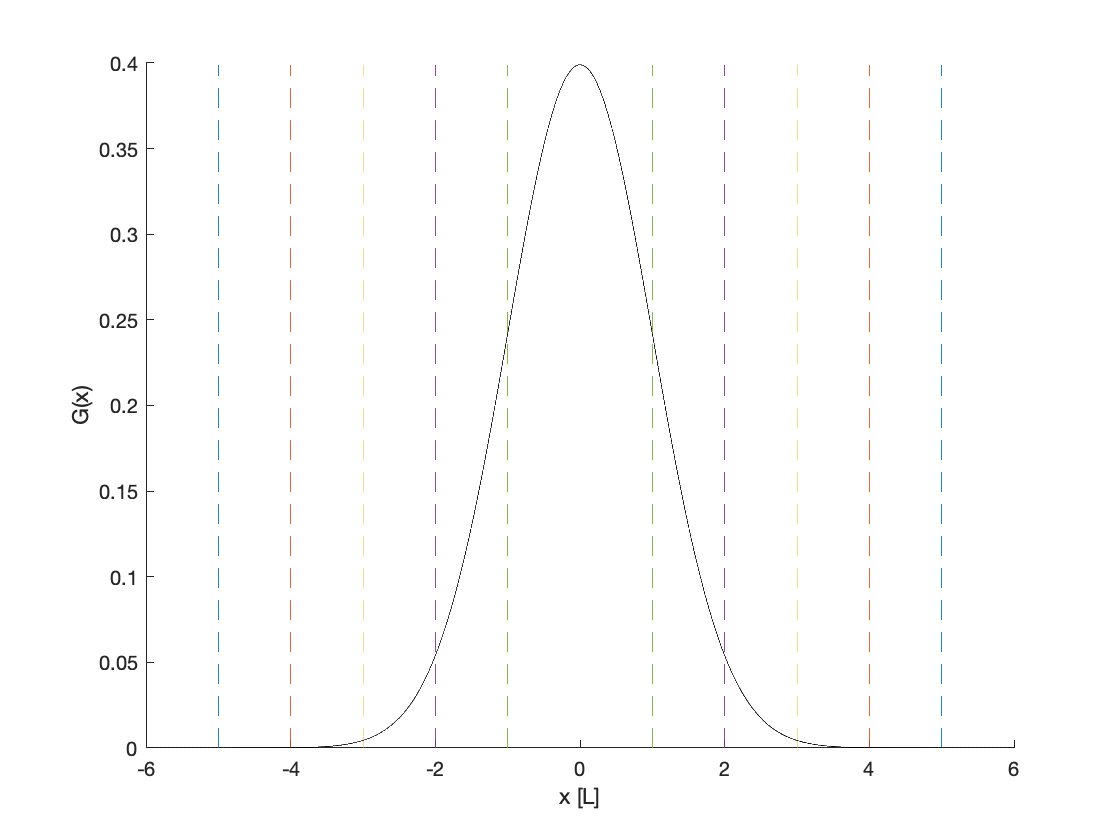

G_f=exp(-(f.^2)./(2.*sigma_f.^2));

%Find sigma and sigma_f intervals
sigmax = sort(sigma(i).*[-5:-1,1:5]'*[1 1]);
sigmay = repmat([0 max(G)],10,1);
sigma_fx = sigma_f(i).*[1:5]'*[1 1];
sigma_fy = repmat([0 max(G_f)],5,1);
sigma_lx = 1./sigma_fx;
sigma_ly = repmat([0 max(G_f)],5,1);

%PLOTS
figure(1)
c=get(gca,'colororder');
cnew=[c(1:5,:);flipud(c(1:5,:))];
set(gca,'ColorOrder',cnew,'NextPlot', 'replacechildren')
plot(sigmax',sigmay','--');hold on
plot(x,G,'k');
ylabel('G(x)');xlabel('x [L]')
xlim(6.*sigma(i).*[-1 1])

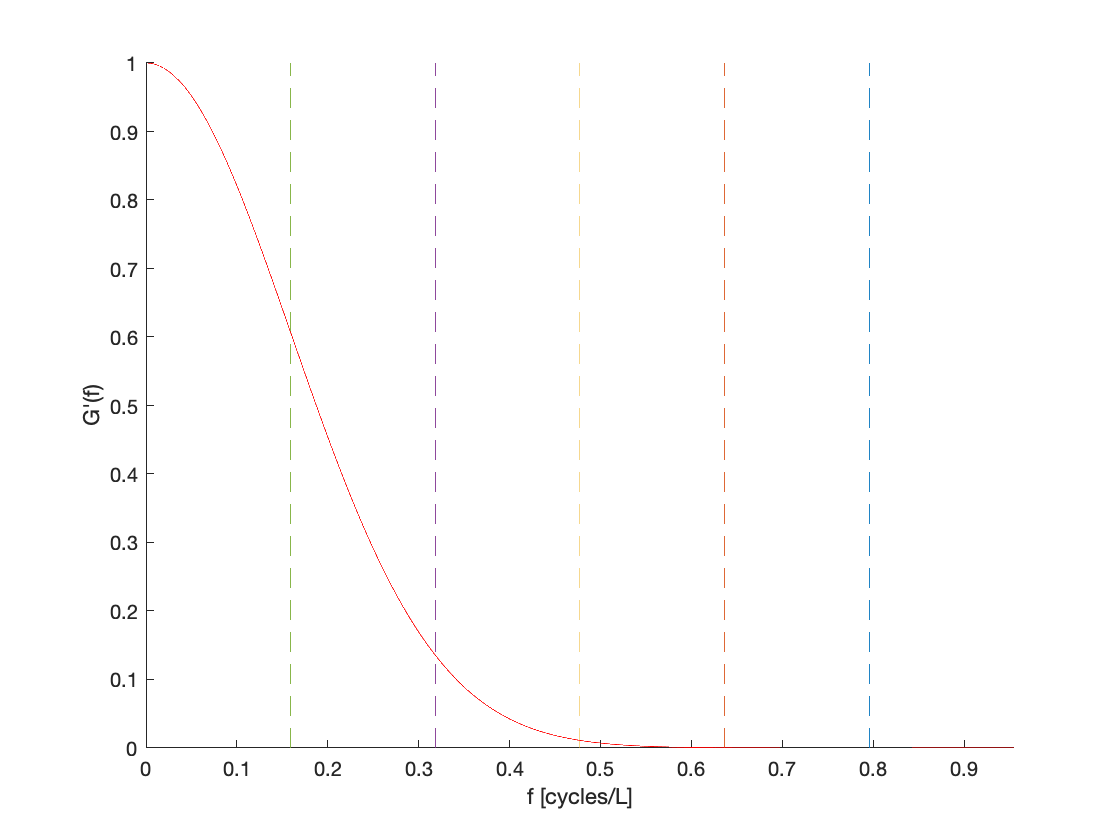


figure(2)
set(gca,'ColorOrder',cnew(6:10,:),'NextPlot', 'replacechildren')
plot(sigma_fx',sigma_fy','--');hold on    
plot(f,G_f,'r');ylabel('G''(f)');xlabel('f [cycles/L]')
xlim([0 6.*sigma_f(i)])

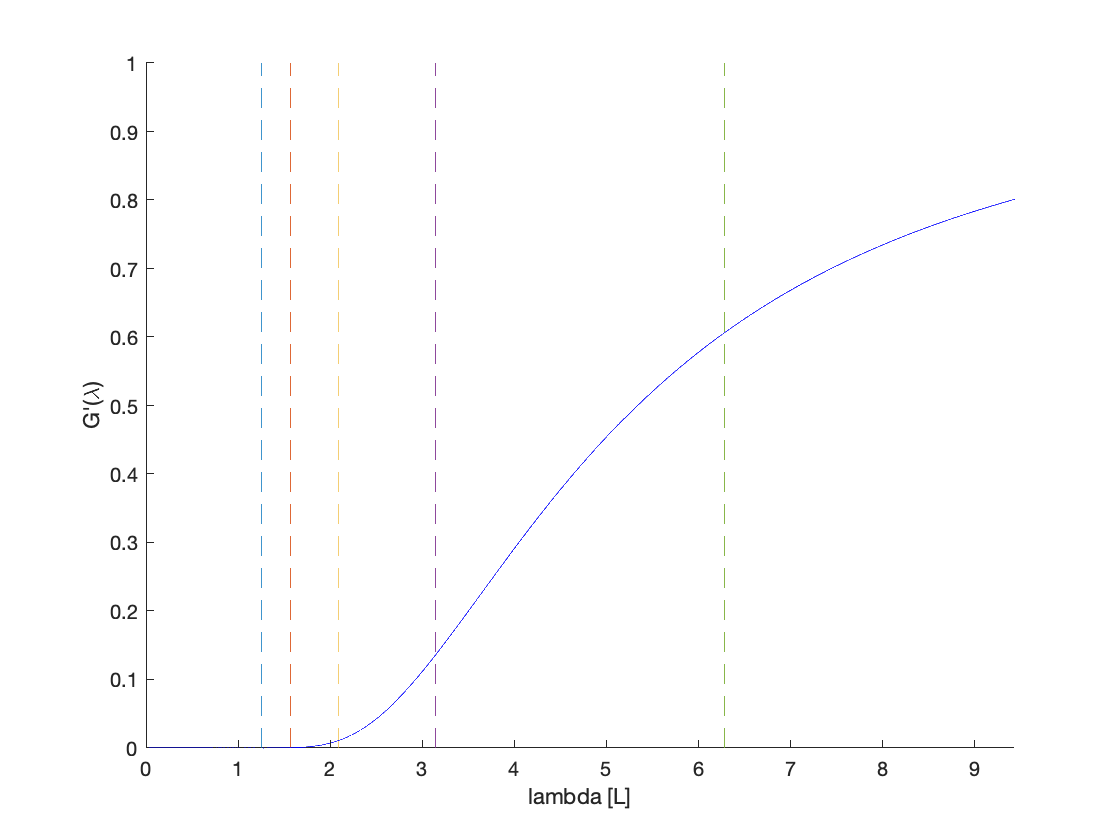


figure(3)
set(gca,'ColorOrder',cnew(6:10,:),'NextPlot', 'replacechildren')
plot(sigma_lx',sigma_ly','--');hold on        
plot(lambda,G_f,'b');ylabel('G''(\lambda)');xlabel('lambda [L]')
xlim([0 1.5.*sigma_l(i)])

$1\sigma =68\ldotp 27%$, $2\sigma =95\ldotp 45%$, $3\sigma =99\ldotp 73%$ of data.

Gaussian frequency response $\hat{G} \left(f\right)$ is essentially zero by $3\sigma_f$.

Gaussian standard deviation $\sigma$ and frequency response standard deviation $\sigma_f$ are related by: $\sigma_f =\frac{1}{2\pi \sigma }$. 

Spatial wavelength $\lambda =\frac{1}{f}$ where $f$ is frequency is $\frac{\mathrm{cycles}}{\left\lbrack L\right\rbrack }$. 

Therefore, the wavelength by which amplitude is nearly fully attenuated is $\lambda_0 =\frac{2\pi \sigma }{3}$.

sigma=1

sigma = 1

lambda0 = 2*pi*sigma/3

lambda0 = 2.0944

Inverse: to fully attenuate all wavelengths $<\lambda {\;}_0$, use $\sigma_f ~\frac{f_0 }{3}=\frac{1}{3\lambda_0 }\to \sigma =\frac{3\lambda_0 }{2\pi }$. 

lambda0 = 1

lambda0 = 1

sigma=3*lambda0/(2*pi)

sigma = 0.4775

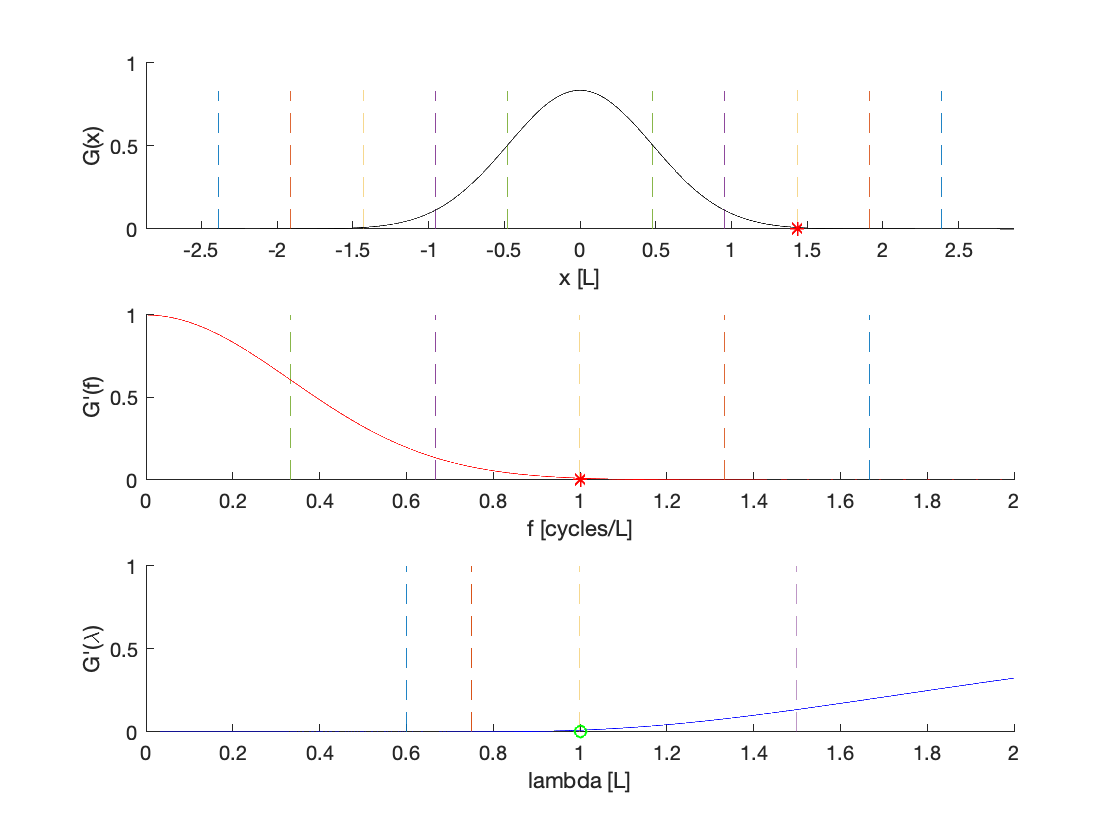


G=(1./(sqrt(2*pi).*sigma)).*exp(-(x.^2)./(2.*sigma.^2));
sigma_f=1./(2.*pi.*sigma);
sigma_l=1./sigma_f;
G_f=exp(-(f.^2)./(2.*sigma_f.^2));

%Find sigma and sigma_f intervals
sigmax = sort(sigma.*[-5:-1,1:5]'*[1 1]);
sigmay = repmat([0 max(G)],10,1);
sigma_fx = sigma_f(i).*[1:5]'*[1 1];
sigma_fy = repmat([0 max(G_f)],5,1);
sigma_lx = 1./sigma_fx;
sigma_ly = repmat([0 max(G_f)],5,1);


%PLOTS
figure(4)
subplot(3,1,1)
c=get(gca,'colororder');
cnew=[c(1:5,:);flipud(c(1:5,:))];
set(gca,'ColorOrder',cnew,'NextPlot', 'replacechildren')
plot(sigmax',sigmay','--');hold on
plot(x,G,'k');
plot(3*sigma,0,'r*')
ylabel('G(x)');xlabel('x [L]')
xlim(6.*sigma.*[-1 1])

subplot(3,1,2)
set(gca,'ColorOrder',cnew(6:10,:),'NextPlot', 'replacechildren')
plot(sigma_fx',sigma_fy','--');hold on    
plot(f,G_f,'r');ylabel('G''(f)');xlabel('f [cycles/L]')
plot(3*sigma_f,0,'r*')
xlim([0 6.*sigma_f])

subplot(3,1,3)
set(gca,'ColorOrder',cnew(6:10,:),'NextPlot', 'replacechildren')
plot(sigma_lx',sigma_ly','--');hold on        
plot(lambda,G_f,'b');ylabel('G''(\lambda)');xlabel('lambda [L]')
plot(sigma_l,0,'r*')
plot(lambda0,0,'go')
xlim([0 2.*lambda0])